clear all;

% Other
g = -9.82;
m = 4;
Fmg = m*g;

% Spring paramters
K = 2;
L0 = 1;

% Damp parameter
cd = 2;

h = 0.1;
t_end = 25;
v = zeros(t_end/h, 2);
p = zeros(t_end/h, 2);

% Particle 1
v(1,1) = 0;
p(1,1) = -5;

% Particle 2
v(1,2) = 0;
p(1,2) = 1;

q_position = 2;

% Anonymous function to move code out from the for loop
calc_f_spring = @(p, q)( K*(L0 - abs(p-q))*((p-q)/abs(p-q)));

i = 2;
for t = h:h:t_end-h

    % Calculate the forces => gives us acceleration of each particle
    % DOING p(1,2) 
    Fspring_q = calc_f_spring(p(i-1,2), q_position);
    Fspring_1 = calc_f_spring(p(i-1,2), p(i-1,1));
    Fdamp = -cd*v(i-1,2);
    a = (1/m)*(Fmg + Fspring_q + Fspring_1 + Fdamp);
   
    % Perform numerical method: euler
    [v(i,2) p(i,2)] = numericalMethod(v(i-1,2), p(i-1,2), h, a, 'runge-kutta');
    
    % DOING p(1,1) 
    Fspring = calc_f_spring(p(i-1, 1), p(i-1, 2));
    Fdamp = -cd*v(i-1,1);
    a = (1/m)*(Fmg+Fspring+Fdamp);
    
    % Perform numerical method: euler
    [v(i,1) p(i,1)] = numericalMethod(v(i-1,1), p(i-1,1), h, a,'runge-kutta');
    
    i = i+1;
end

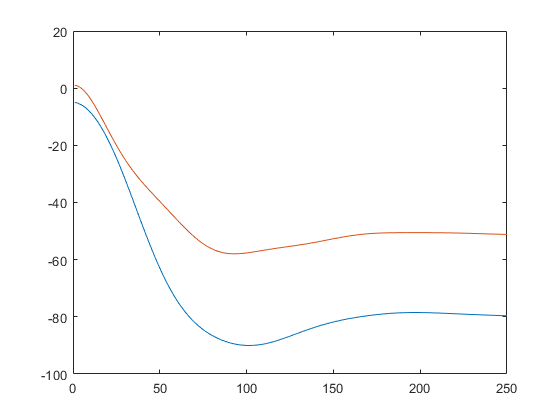

clf
plot(p(:,1));
hold on;
plot(p(:,2));